# Bode plots

## Constant

H(s) = k

s = tf('s');

k = 2;

num = [k];
denom = [1];
H = tf(num,denom)

H =
 
  2
 
Static gain.



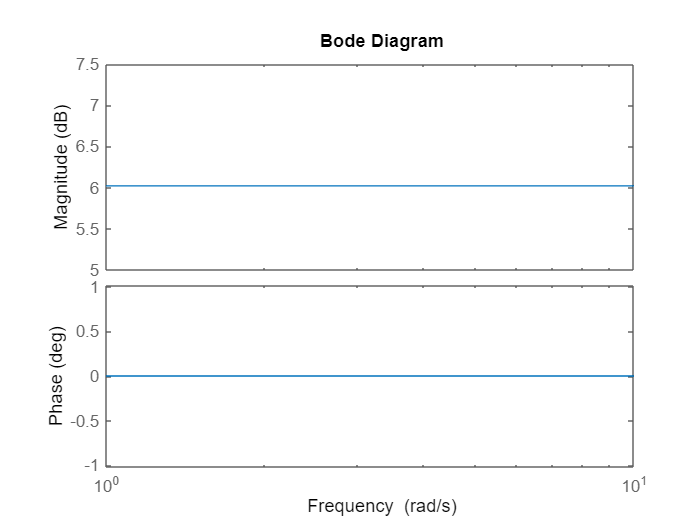

bodeplot(H)

## Poles and zeros at origin

H(S) = 1/S or S

num = [1];
denom = [1,0];

% Pole at origin
H = tf(num,denom)

H =
 
  1
  -
  s
 
Continuous-time transfer function.



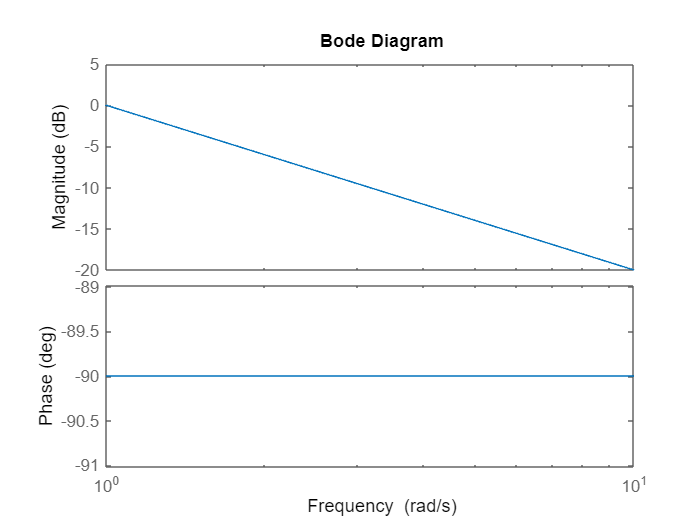

bodeplot(H)

num = [1,0];
denom = [1];
% Zero at origin
H = tf(num,denom)

H =
 
  s
 
Continuous-time transfer function.



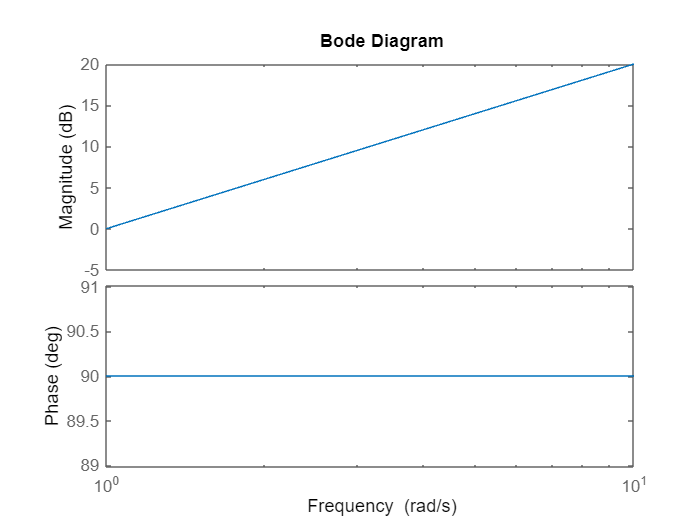

bodeplot(H)

## Real poles and zeros

H(S) = w0/(S+wo) 

        or 

(S+w0)/w0

w0 = 100; % break frequency
num = [w0];
denom = [1,w0];
H = tf(num,denom)

H =
 
    100
  -------
  s + 100
 
Continuous-time transfer function.



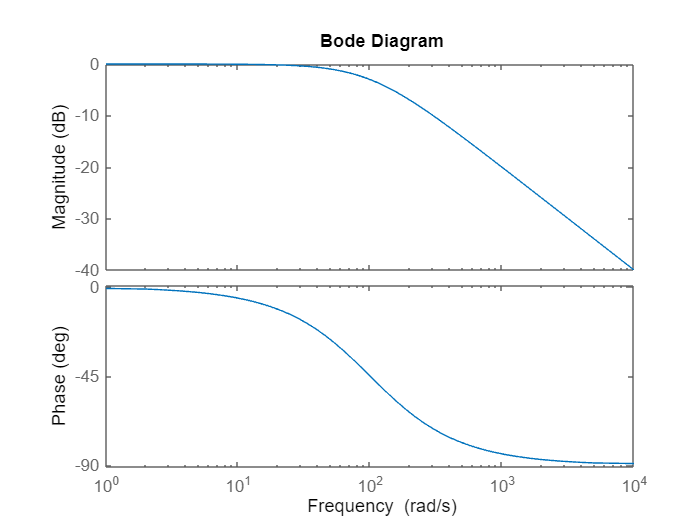

bodeplot(H)

num = [1,w0];
denom = [w0];
H = tf(num,denom)

H =
 
  s + 100
  -------
    100
 
Continuous-time transfer function.



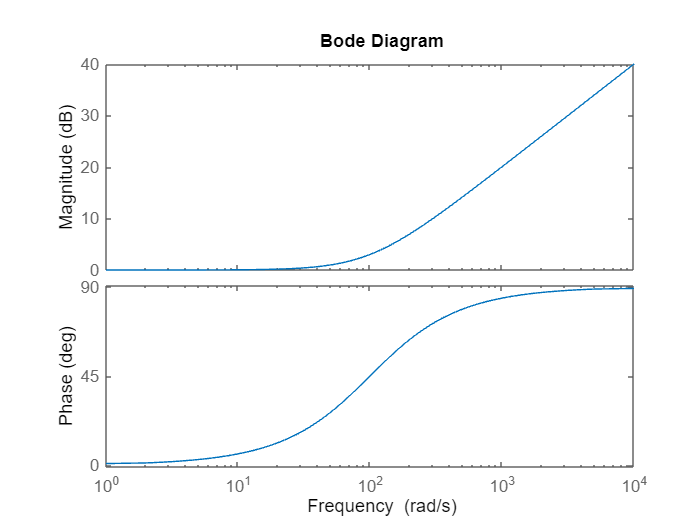

bodeplot(H)

## Complex poles and zeros

H(S) = w0^2/(S^2+2*z*w0+w0^2) 

                    or 

(S^2+2*z*w0+w0^2)/w0^2

z = 0.8; % zeta: defines whether a system has complex or real poles (z<1 will give complex conjugate poles)
w0 = 100;

num = [w0^2];
denom = [1,2*z*w0,w0^2];
H = tf(num,denom)

H =
 
         10000
  -------------------
  s^2 + 160 s + 10000
 
Continuous-time transfer function.



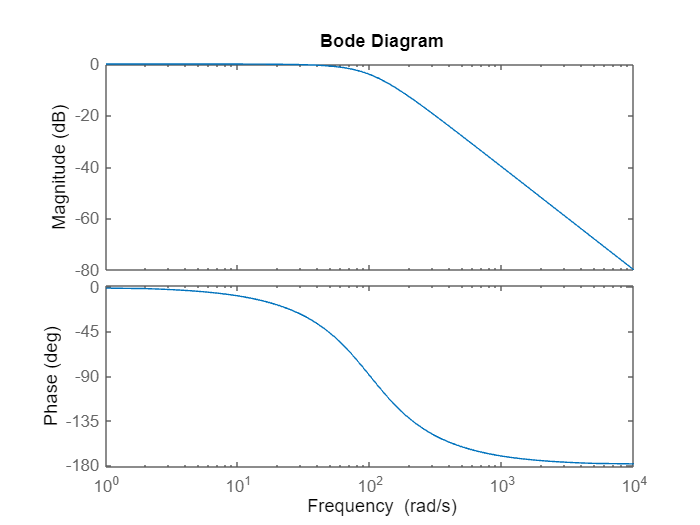

bodeplot(H)


num = [1,2*z*w0,w0^2];
denom = [w0^2];
H = tf(num,denom)

H =
 
  s^2 + 160 s + 10000
  -------------------
         10000
 
Continuous-time transfer function.



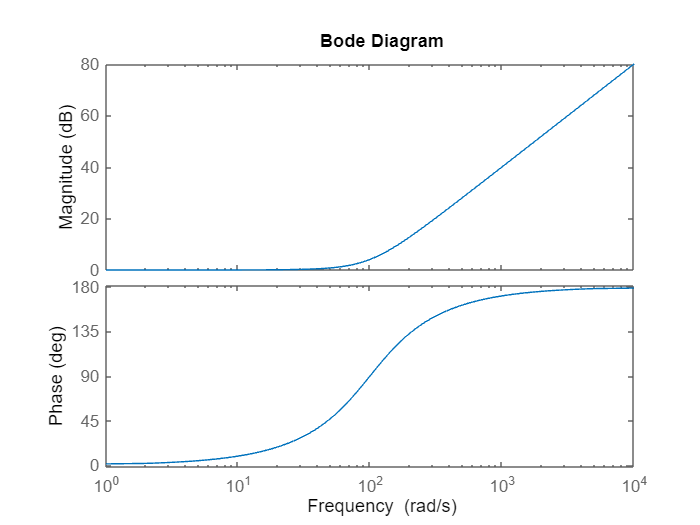

bodeplot(H)